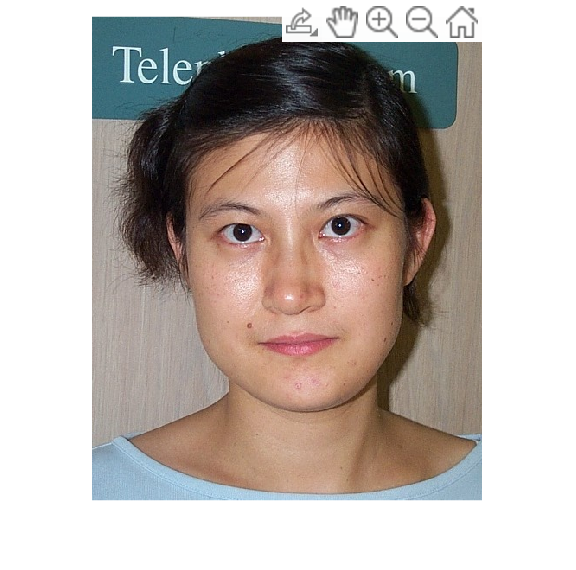

clc;  
clear; 

img = imread("Images/DB0/db0_3.jpg"); 
img_gray = grayworld(img);
img_white = whiteworld(img);
imshow(img); 

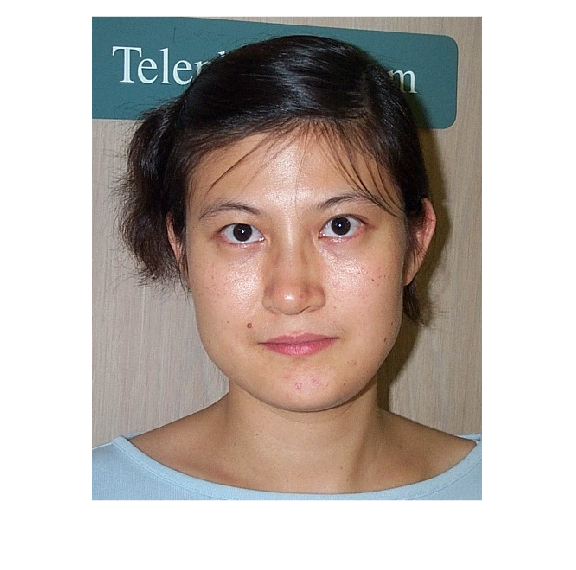

%imshow(img_gray); 
imshow(img_white); 

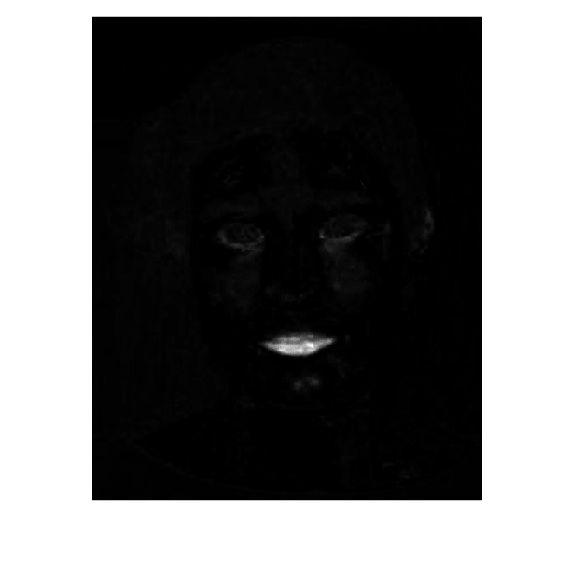


eyeChrome = eyemapC(img);
eyeLum = eyemapL(img);
mouth = mouthmap(img); 
imshow(mouth)

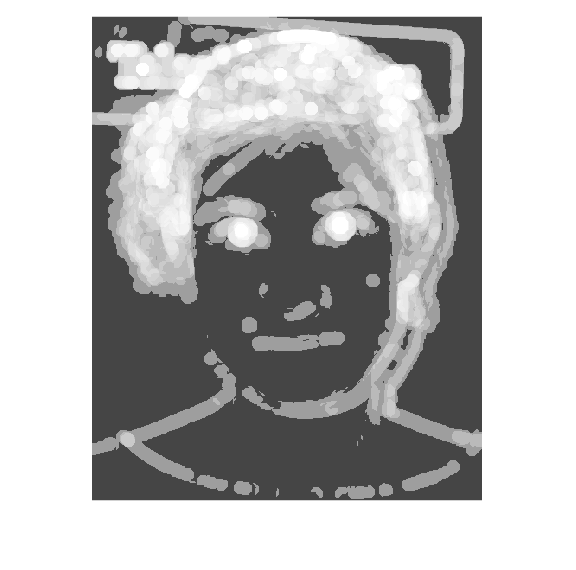

imshow(eyeLum)

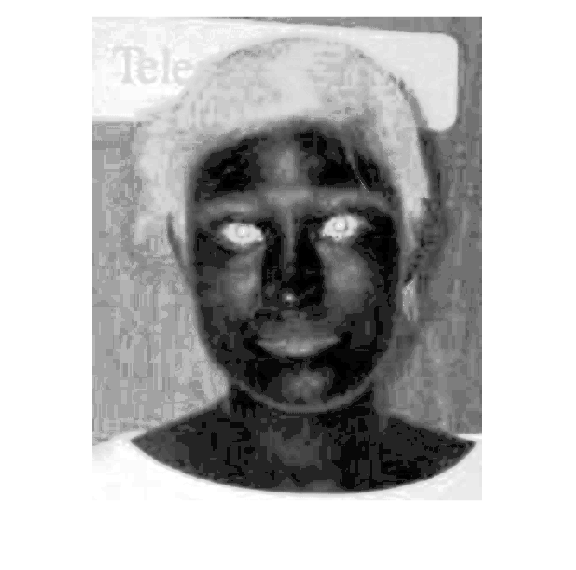

imshow(eyeChrome)

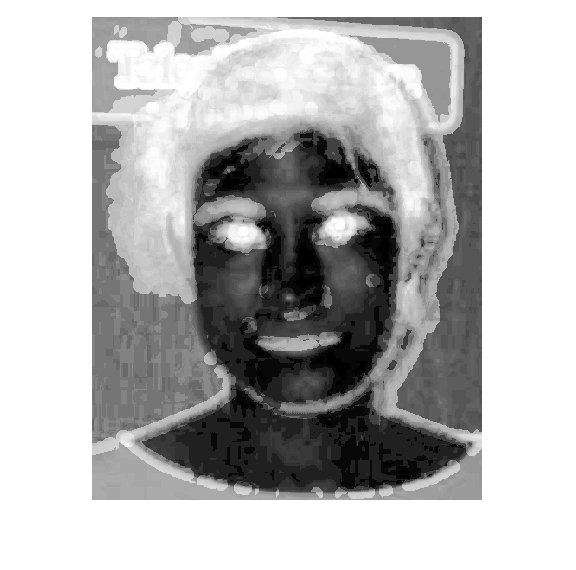


eyemap = eyeChrome.*eyeLum;
eyemap = histeq(eyemap);
%se = strel('disk', 4);
%dilated = imdilate(eyemap, se); 
imshow(eyemap);

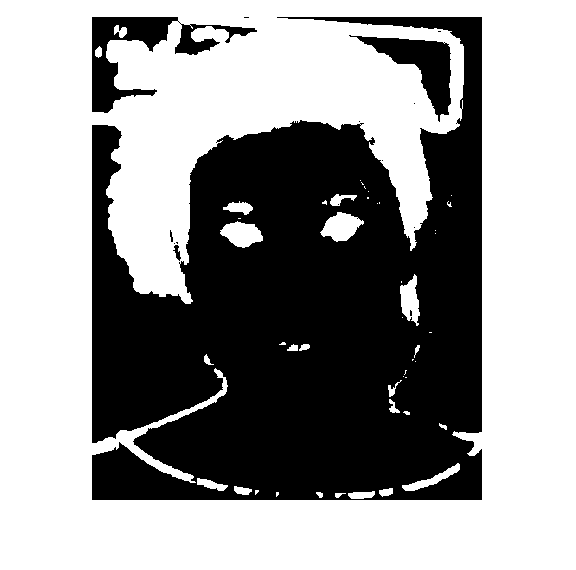


eyemap = eyemap > 0.7;

imshow(eyemap);


mask = facemask(img_white);

SE2 = strel is a disk shaped structuring element with properties:

      Neighborhood: [7×7 logical]
    Dimensionality: 2


One iteration
One iteration
One iteration
One iteration
One iteration
One iteration
One iteration


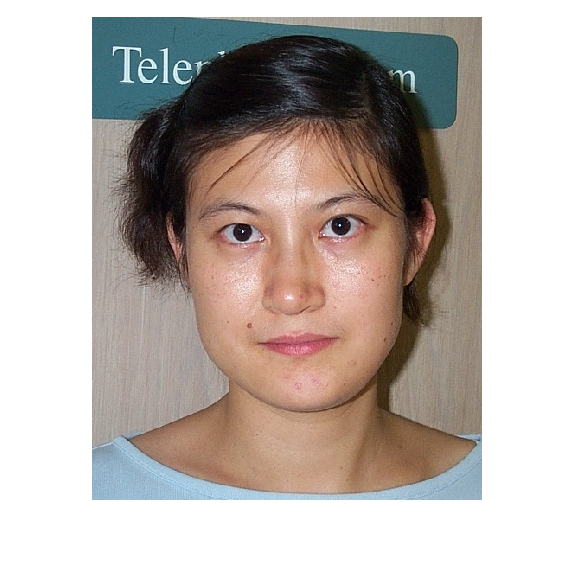

imshow(img_white)

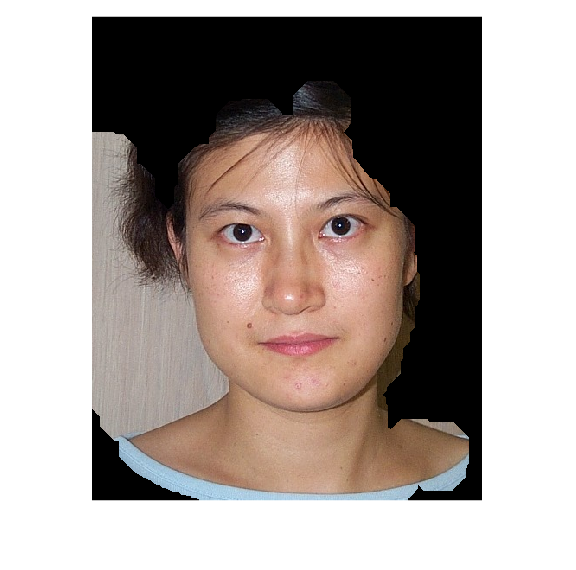

imshow(mask)

%img_ycbcr = rgb2ycbcr(img);
%imshow(img_ycbcr); 

%img_hsv = rgb2hsv(img);
%imshow(img_hsv); 